# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Data and problem

n=3; % data dimension
k=5; % number of matrices
p=n; % size of factorization X of barycenter B
r=n; % size of factorization Y of data A
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

## Gradient

checkgradient(prob);

The slope should be 2. It appears to be: 2.
If it is far from 2, then directional derivatives might be erroneous.


The residual should be 0, or very close. Residual: 3.0814e-15.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


## Hessian

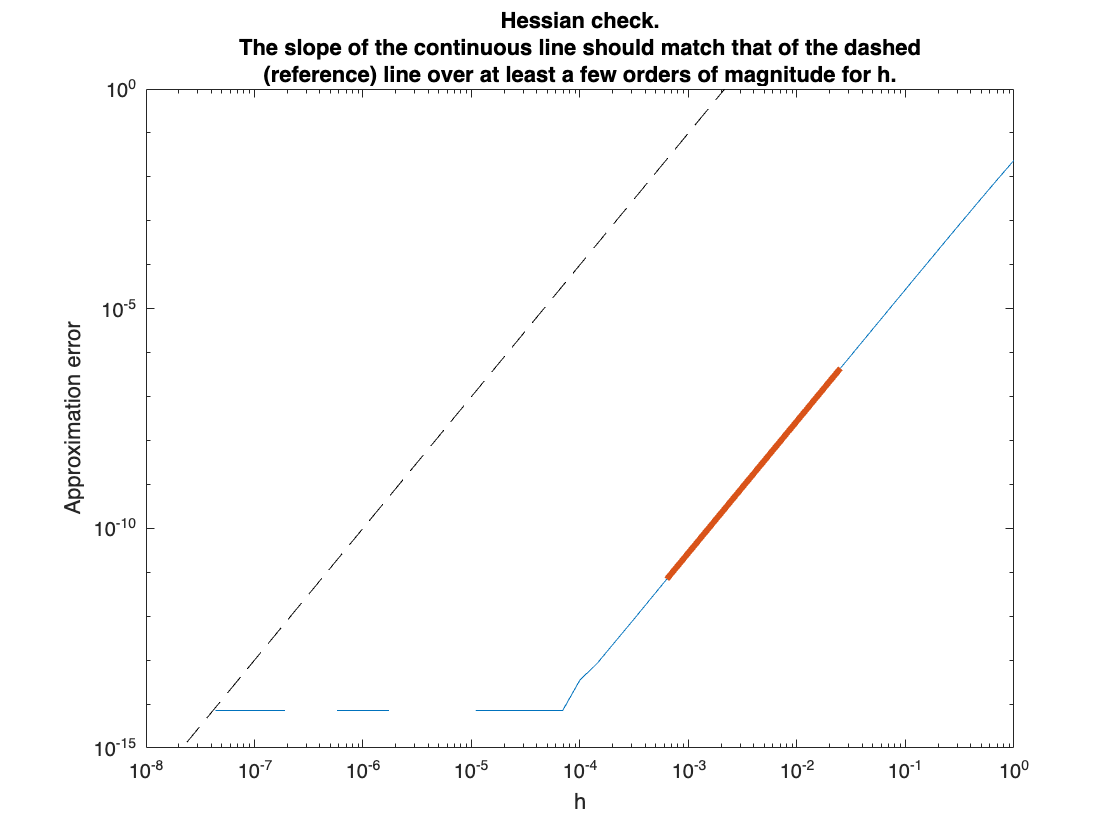

The slope should be 3. It appears to be: 3.00005.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 6.77705e-16.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 2.09601e-15 (norm of H[a*d1+b*d2]: 12.2121)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: -1.25767 - -1.25767 = 0.
If it is far from 0, then the Hessian is not symmetric.


checkhessian(prob);

## Optimization

options.debug=1;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +6.2067150386730290e+01   3.288694e+01
**************************************************************************************************
DBG:     rhonum : 1.816744e+01
DBG:     rhoden : 1.816998e+01
DBG:   new f(x) : +4.389971e+01
DBG: actual rho : 9.998600e-01
DBG:   used rho : 9.998600e-01
acc TR+       1   +4.3899709976770723e+01   2.644827e+01           1           1           1   exceeded trust region
DBG: cos ang(eta, gradf): -1
**************************************************************************************************
DBG:     rhonum : 2.448822e+01
DBG:     rhoden : 2.450747e+01
DBG:   new f(x) : +1.941149e+01
DBG: actual rho : 9.992144e-01
DBG:   used rho : 9.992144e-01
acc TR+       2   +1.9411490993076953e+01   1.356288e+01           1           1           1   exceeded trust region
DBG: cos ang(eta, gradf): -1.000000e+00
************************

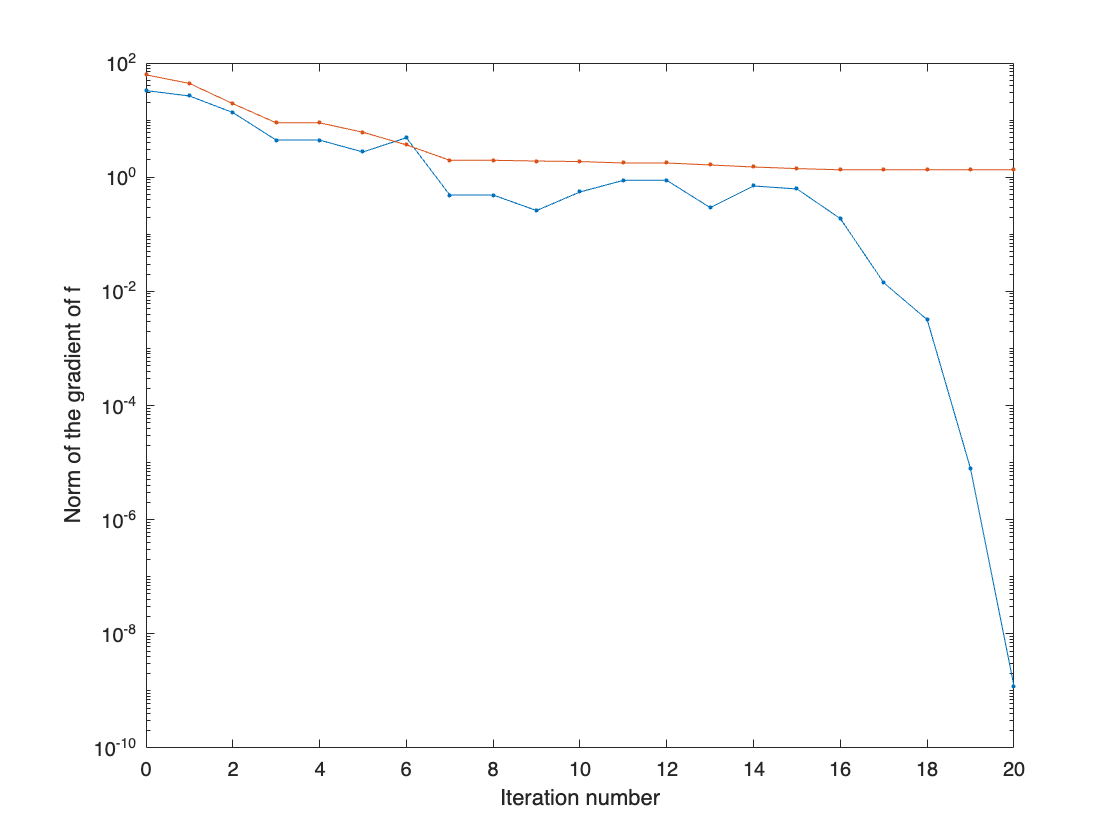

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
ylabel('Norm of the gradient of f');

legend('gradient norm','cost')